## Figure 5

clc, clear, close all;

% Generamos los blobs artificialmente (usamos Fermi-Dirac)
blob = @(x,e1,e2) 1./(exp((x+e1)/0.2) + 1) - 1./(exp((x+e2)/0.2) + 1);
x = linspace(-5, 5, 150);

blob_s = blob(x,-1.5,1.5);
blob_l = blob(x,-3.0,3.0);
blob_m = blob(x,-3,-1) + blob(x,1,3);


% Generamos las gausianas
gauss = @(x,sigma) 1/2/pi/sigma^2*exp(-x.^2./sigma/2);

sigma_s = 0.57;
sigma_l = 1.6;

gauss_s = gauss(x,sigma_s);
gauss_l = gauss(x,sigma_l);

% Calculamos los LoG
LoG = @(x,sigma) - 1/pi/sigma^4 * (1 - x.^2/sigma^2/2) .* gauss(x,sigma);

LoG_s = LoG(x,sigma_s);
LoG_l = LoG(x,sigma_l);

% Convolucionamos NLoG con el blob
conv_1 = conv(blob_s,LoG_s,"same");
conv_2 = conv(blob_l,LoG_s,"same");
conv_3 = conv(blob_l,LoG_l,"same");
conv_4 = conv(blob_m,LoG_s,"same");

Nconv_1 = conv(blob_s,sigma_s^2*LoG_s,"same");
Nconv_2 = conv(blob_l,sigma_s^2*LoG_s,"same");
Nconv_3 = conv(blob_l,sigma_l^2*LoG_l,"same");
Nconv_4 = conv(blob_m,sigma_s^2*LoG_s,"same");

Tenemos los cálculos, generamos la imagen.

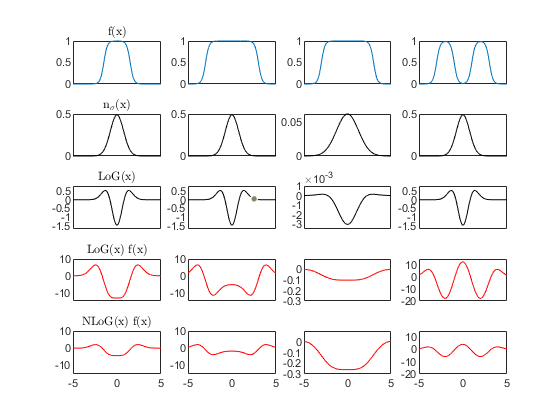

figure(1), clf;
tickCell = {'XTickLabel',{}};

% Dibujamos los blobs
subplot(5,4,1)
plot(x,blob_s), set(gca,tickCell{:});
title("f(x)",'interpreter','latex')
subplot(5,4,2)
plot(x,blob_l), set(gca,tickCell{:});
subplot(5,4,3)
plot(x,blob_l), set(gca,tickCell{:});
subplot(5,4,4)
plot(x,blob_m), set(gca,tickCell{:});

% Dibujamos las gaussianas
subplot(5,4,5)
plot(x,gauss_s, "k"), set(gca,tickCell{:});
title("n$_\sigma$(x)",'interpreter','latex')
subplot(5,4,6)
plot(x,gauss_s, "k"), set(gca,tickCell{:});
subplot(5,4,7)
plot(x,gauss_l, "k"), set(gca,tickCell{:});
subplot(5,4,8)
plot(x,gauss_s, "k"), set(gca,tickCell{:});

% Dibujamos los LoG
subplot(5,4,9)
plot(x,LoG_s, "k"), set(gca,tickCell{:});
title("LoG(x)",'interpreter','latex')
ylim([-1.7,0.8])
subplot(5,4,10)
plot(x,LoG_s, "k"), set(gca,tickCell{:});
ylim([-1.7,0.8])
subplot(5,4,11)
plot(x,LoG_l, "k"), set(gca,tickCell{:});
ylim([-3.5e-3,1e-3])
subplot(5,4,12)
plot(x,LoG_s, "k"), set(gca,tickCell{:});
ylim([-1.7,0.8])

% Dibujamos convolución con LoG
subplot(5,4,13)
plot(x,conv_1, "r"), set(gca,tickCell{:});
title("LoG(x) f(x)",'interpreter','latex')
ylim([-15,10])
subplot(5,4,14)
plot(x,conv_2, "r"), set(gca,tickCell{:});
ylim([-15,10])
subplot(5,4,15)
plot(x,conv_3, "r"), set(gca,tickCell{:});
ylim([-0.3,0.1])
subplot(5,4,16)
plot(x,conv_4, "r"), set(gca,tickCell{:});
ylim([-20,15])

% Dibujamos convolución con NLoG
subplot(5,4,17)
plot(x,Nconv_1, "r")
title("NLoG(x) f(x)",'interpreter','latex')
ylim([-15,10])
subplot(5,4,18)
plot(x,Nconv_2, "r")
ylim([-15,10])
subplot(5,4,19)
plot(x,Nconv_3, "r")
ylim([-0.3,0.1])
subplot(5,4,20)
plot(x,Nconv_4, "r")
ylim([-20,15])